9.26

close all
clear 
clc

mot.k = 5.2;
mot.T = 0.03;
Td = 0.01;

s = tf('s');
Pm = mot.k  / (s * (mot.T * s + 1));
Pd = 1 / (Td * s + 1);

P = minreal(Pm * Pd, 1e-6);

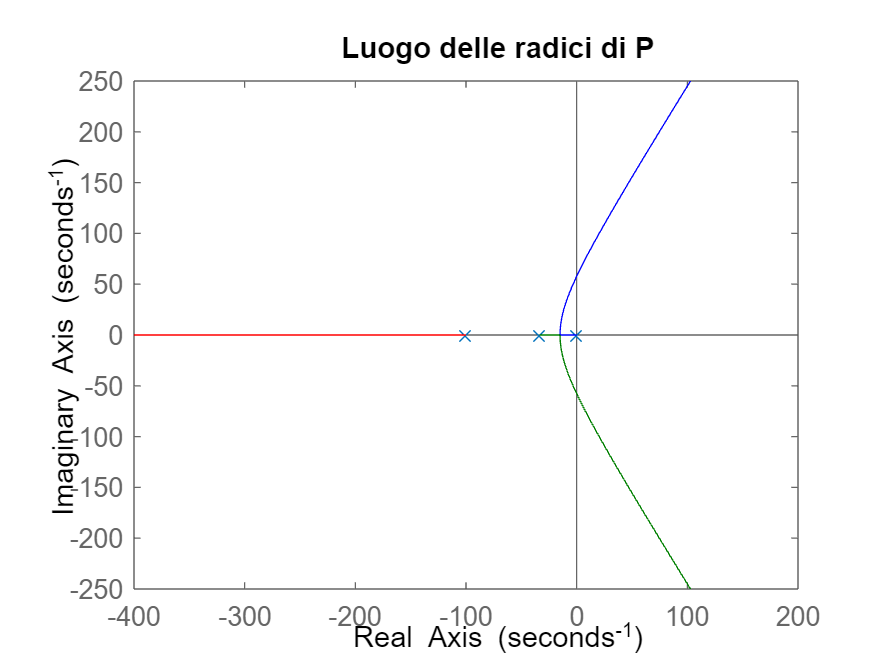

close all
figure(1)
rlocus(P)
title("Luogo delle radici di P")

Ku = margin(P)

Ku = 25.6410

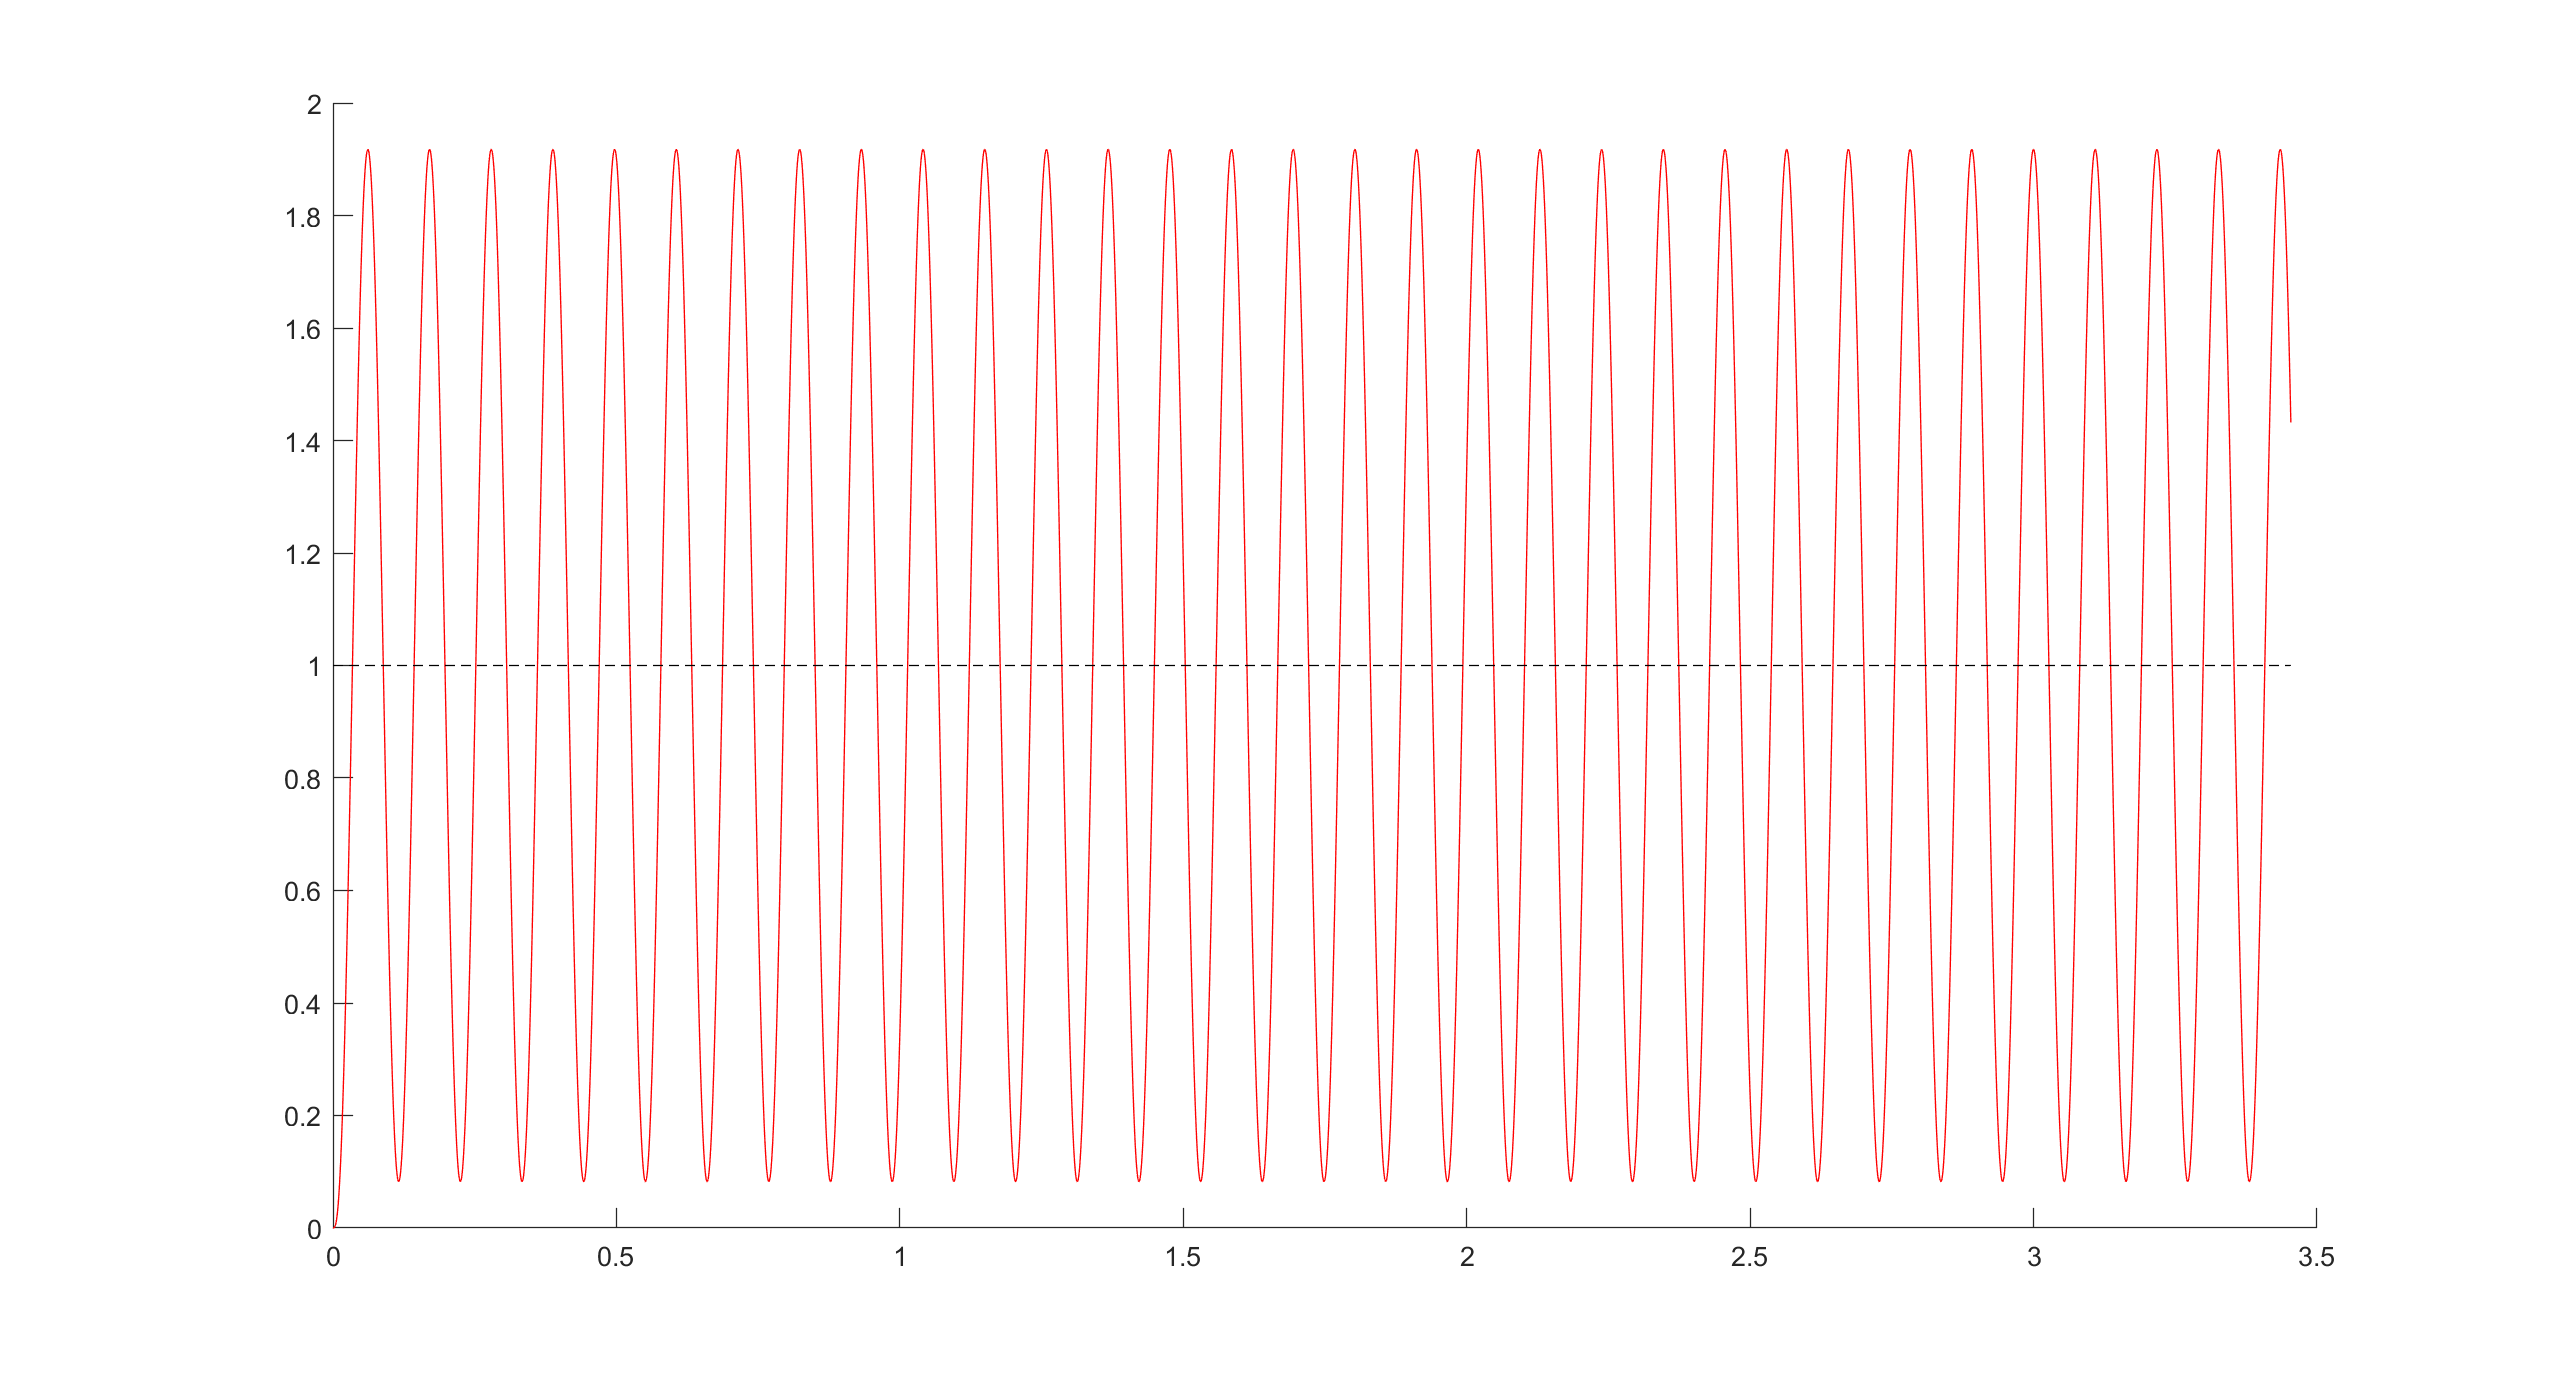

T = minreal(feedback(Ku * P, 1), 1e-6);
[y, t] = step(T);
close all
figure(2)
hold on
plot(t, y, "r")
plot([t(1), t(end)], [1, 1], "k--")
[X, Y] = ginput(2);

Tu = X(2) - X(1);


pid.Kp = 0.6 * Ku;
pid.Ti = 0.5 * Tu;
pid.Td = 0.125 * Tu;

C = minreal(pid.Kp * (1 + 1 / (s * pid.Ti) + s * pid.Td), 1e-6);

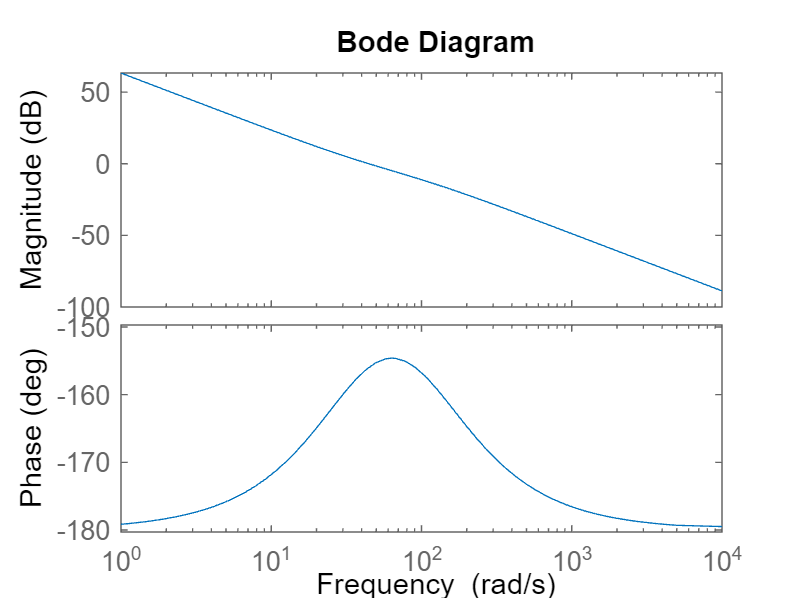

L = P * C;
close all
figure(3)
bode(L)

[~, phim, ~, wgc] = margin(L)

phim = 24.0348

wgc = 44.6026

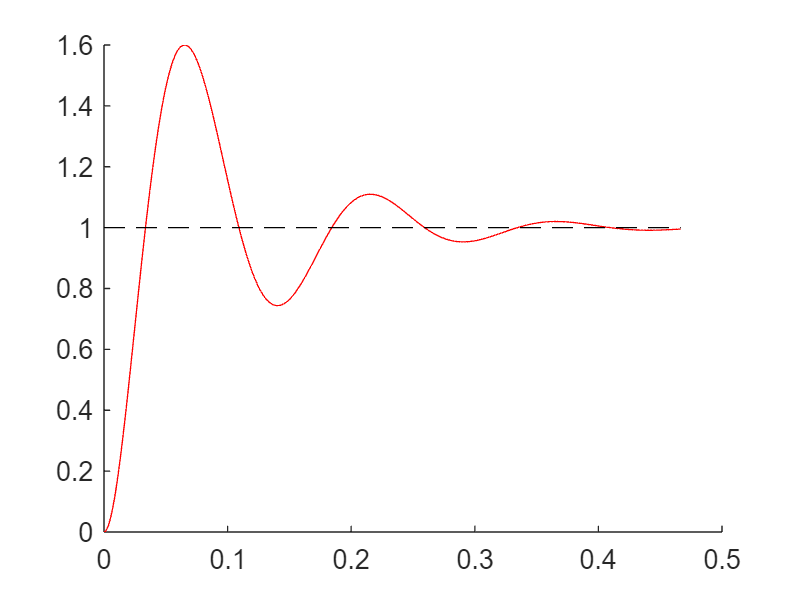

T1 = minreal(feedback(L, 1), 1e-6);
[y1, t1] = step(T1);
close all
figure(2)
hold on
plot(t1, y1, "r")
plot([t1(1), t1(end)], [1, 1], "k--")

infos = stepinfo(T1, "SettlingTimeThreshold", 0.05);
infos.Overshoot

ans = 59.9949

infos.SettlingTime

ans = 0.2438

9.38